# Anden lektion - Frie dæmpede svingninger

clear

syms zeta lambda t A wn k m



eq = A*lambda^2*exp(lambda*t) + 2*zeta*A*wn*lambda*exp(lambda*t) + wn^2*A*exp(lambda*t) == 0



sol = solve(eq, lambda)
simplify(sol)


%%%%


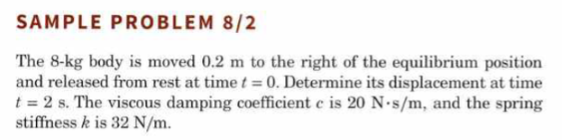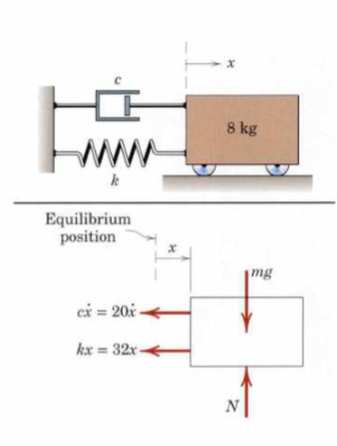

clear

% Data fra opgaven
m = 8;  x0 = 0.2;   t0 = 0; t1 = 2; Cd = 20; k = 32;

% Formler

wn1 = sqrt(k/m)
zeta1 = Cd/(2*m*wn1)
wd1 = wn1*sqrt(1 - zeta1^2)

% Diff ligning
syms x(t) zeta lambda t A wn k m C wd psi x

x_plac = C*exp(-zeta*wn*t) * sin(wd*t + psi) == x0;
% Til t0
x_plac_numt0 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t0]),3)
% til t1
x_plac_numt1 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t1]),3)

x_vel = diff(x_plac, t) == 0
% til t0
x_vel_numt0 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t0]),3)
% til t1
x_vel_numt1 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t1]),3)


eqst0 = [x_vel_numt0, x_plac_numt0];
eqst1 = [x_vel_numt1, x_plac_numt1];
unks = [C, psi];

solt0 = solve(eqst0, unks)
solt1 = solve(eqst1, unks)

solt0.C(1)
solt0.psi(1)


syms func(t)
func(t) = solt0.C(1)*exp(-zeta1*wn1*t) * sin(wd1*t + solt0.psi(1));

fplot(func(t), [0,10]), grid()

clear
% Data fra opgaven
m = 50;  x0 = 0.15;   t0 = 0; t1 = 0.5; Cd = 200; k = 200;

% Formler

wn1 = sqrt(k/m)
zeta1 = Cd/(2*m*wn1)
wd1 = wn1*sqrt(1 - zeta1^2)

syms A1 A2 t x1

x_plac_t0 = (A1 + A2*t)*exp(-wn1*t) == x0
x_plac_t1 = (A1 + A2*t)*exp(-wn1*t) == x1
x_vel = diff(x_plac_t0, t)


eq1 = x_plac_t0 == x0;
eq2 = x_vel == x1

eqs = [eq1, eq2];
vars = [A1, A2];

sols = solve(eqs, vars);
sols.A1
A1_ny = subs(sols.A1, t, t0)
A2_ny = subs(sols.A2, t, t0)

svar = subs(x_plac_t1, [A1, A2, t], [A1_ny, A2_ny, t1]);
vpa(svar, 4)



clear all
format short
% Data fra opgaven
m = 50;  x0 = 0.15;   t0 = 0; t1 = 0.5; Cd = 300; k = 200;

% Formler

wn = sqrt(k/m)
zeta = Cd/(2*m*wn)
wd = wn*sqrt(1 - zeta^2)

% Diff ligninger (skal rettes lidt til) - plus conditions

syms A1 A2 t x1

x_plac_t0 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x0;
x_plac_t1 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x1;

x_vel = diff(x_plac_t0, t);


eq1 = x_plac_t0 == x0;
eq2 = x_vel == x1;

eqs = [eq1, eq2];
vars = [A1, A2];

% Konstanterne A1 og A2 udregnes, og sættes ind i diff ligningerne sammen
% med t1

sols = solve(eqs, vars);

A1_ny = vpa(subs(sols.A1, t, t0),3)
A2_ny = vpa(subs(sols.A2, t, t0),3)

svar = subs(x_plac_t1, [A1, A2, t], [A1_ny, A2_ny, t1]);
vpa(svar, 4)

